# AAE567 HW4

syms x v y
y = x+v

$$y = v+x$$

g = [1;y;y^2];

fx = 1/10;
fv = 1/4;
fxy = 1/40;

Rxg = int(fv * int(fx*x*g', x, 0, 10), 0, 4)

$$Rxg = \left(\begin{array}{ccc} 5 & \frac{130}{3} & 410 \end{array}\right)$$

Rg = int(fv * int(fx*g*g', x, 0, 10), 0, 4)

$$Rg = \left(\begin{array}{ccc} 1 & 7 & \frac{176}{3}\\ 7 & \frac{176}{3} & 546\\ \frac{176}{3} & 546 & \frac{81568}{15} \end{array}\right)$$

Rx = int(fx*x*x',x,0,10)

$$Rx = \frac{100}{3}$$


M = Rxg*inv(Rg)

$$M = \left(\begin{array}{ccc} -\frac{30}{29} & \frac{25}{29} & 0 \end{array}\right)$$

M = eval(M)

M =    -1.0345    0.8621         0



error = Rx - M*Rxg'

$$error = \frac{100}{87}$$

error = eval(error)

error = 1.1494

y = linspace(0,14,100)

y =          0    0.1414    0.2828    0.4242    0.5657    0.7071    0.8485    0.9899    1.1313    1.2727    1.4141    1.5556    1.6970    1.8384    1.9798    2.1212    2.2626    2.4040    2.5455    2.6869    2.8283    2.9697    3.1111    3.2525    3.3939    3.5354    3.6768    3.8182    3.9596    4.1010    4.2424    4.3838    4.5253    4.6667    4.8081    4.9495    5.0909    5.2323    5.3737    5.5152    5.6566    5.7980    5.9394    6.0808    6.2222    6.3636    6.5051    6.6465    6.7879    6.9293



x1 = 130*y/176;
x2 = -30/29 + 25*y/29;
x3 = polyval(fliplr(M), y)

x3 =    -1.0345   -0.9126   -0.7907   -0.6688   -0.5468   -0.4249   -0.3030   -0.1811   -0.0592    0.0627    0.1846    0.3065    0.4284    0.5503    0.6722    0.7941    0.9161    1.0380    1.1599    1.2818    1.4037    1.5256    1.6475    1.7694    1.8913    2.0132    2.1351    2.2571    2.3790    2.5009    2.6228    2.7447    2.8666    2.9885    3.1104    3.2323    3.3542    3.4761    3.5980    3.7200    3.8419    3.9638    4.0857    4.2076    4.3295    4.4514    4.5733    4.6952    4.8171    4.9390


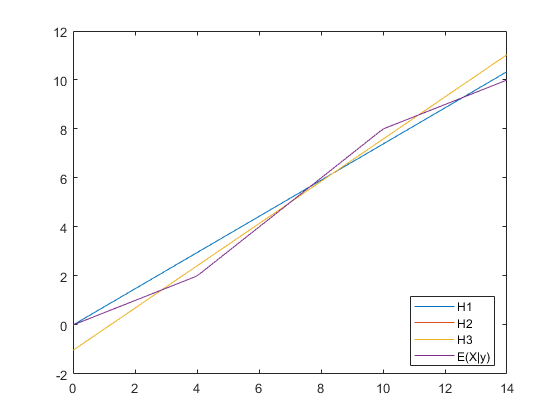


n = 100;
Exy = zeros(1,n);
for i = 1:n
    if y(i) <= 4
        Exy(i) = y(i)/2;
    elseif y(i) <= 10 && y(i) > 4
        Exy(i) = y(i)-2;
    elseif y(i) <= 14 && y(i) > 10
        Exy(i) = (y(i)+6)/2;
    end
end

figure
plot(y,x1)
hold on;
plot(y,x2)
plot(y,x3)
plot(y,Exy)
legend('H1','H2','H3','E(X|y)', 'Location','best')

clear
syms x y
y = log(x);
g = [1;y;y^2];
fy = 1;
fx = 1/x;

Rxg = int(fy * int(fx*x*g', x, 1, exp(1)), 0, 1)

$$Rxg = \left(\begin{array}{ccc} \frac{1934613350591413}{1125899906842624} & \frac{3060513257434037\,\log\left(\frac{3060513257434037}{1125899906842624}\right)}{1125899906842624}-\frac{1934613350591413}{1125899906842624} & \frac{3060513257434037\,{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{2}}{1125899906842624}-\frac{3060513257434037\,\log\left(\frac{3060513257434037}{1125899906842624}\right)}{562949953421312}+\frac{1934613350591413}{562949953421312} \end{array}\right)$$

eval(Rxg)

ans =     1.7183    1.0000    0.7183



Rg = int(fy * int(fx*g*g', x, 1, exp(1)), 0, 1)

$$Rg = \begin{array}{l} \left(\begin{array}{ccc} \log\left(3060513257434037\right)-50\,\log\left(2\right) & \frac{{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{2}}{2} & \sigma_{1}\\ \frac{{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{2}}{2} & \sigma_{1} & \frac{{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{4}}{4}\\ \sigma_{1} & \frac{{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{4}}{4} & \frac{{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{5}}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{3}}{3} \end{array}$$

eval(Rg)

ans =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000



Rx = int(fx*x*x',x, 1,exp(1))

$$Rx = \frac{8099090798701270632748702911993}{2535301200456458802993406410752}$$

eval(Rx)

ans = 3.1945


M = Rxg*inv(Rg)

M = eval(M)

M =     1.0130    0.8511    0.8392



error = Rx - M*Rxg'

$$error = \frac{44539683100762018343376426115\,\log\left(\frac{3060513257434037}{1125899906842624}\right)}{19807040628566084398385987584}-\frac{22591302007063871179854946809\,{\log\left(\frac{3060513257434037}{1125899906842624}\right)}^{2}}{9903520314283042199192993792}+\frac{82364448146637644397654045489}{2535301200456458802993406410752}$$

error = eval(error)

error = 2.7835e-05

n=100

n = 100

y = linspace(0,1,n)

y =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


xhat_3 = polyval(fliplr(M),y)

xhat_3 =     1.0130    1.0217    1.0305    1.0396    1.0488    1.0581    1.0677    1.0774    1.0872    1.0973    1.1075    1.1179    1.1285    1.1392    1.1501    1.1612    1.1725    1.1839    1.1955    1.2072    1.2192    1.2313    1.2436    1.2560    1.2686    1.2814    1.2944    1.3075    1.3208    1.3343    1.3480    1.3618    1.3758    1.3899    1.4043    1.4188    1.4335    1.4483    1.4633    1.4785    1.4939    1.5094    1.5251    1.5410    1.5570    1.5733    1.5896    1.6062    1.6229    1.6398


Exy = exp(y)

Exy =     1.0000    1.0102    1.0204    1.0308    1.0412    1.0518    1.0625    1.0733    1.0842    1.0952    1.1063    1.1175    1.1289    1.1403    1.1519    1.1636    1.1754    1.1873    1.1994    1.2116    1.2239    1.2363    1.2488    1.2615    1.2743    1.2873    1.3003    1.3135    1.3269    1.3403    1.3540    1.3677    1.3816    1.3956    1.4098    1.4241    1.4386    1.4532    1.4679    1.4828    1.4979    1.5131    1.5284    1.5439    1.5596    1.5755    1.5915    1.6076    1.6239    1.6404


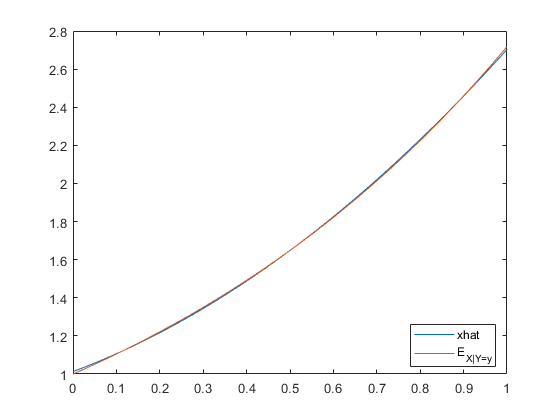

figure
plot(y,xhat_3)
hold on;
plot(y, Exy)
legend('xhat','E_{X|Y=y}','Location','best')

## 1.1

clear
syms x v y
y = x + v;
fx = 1/4;
fv = 1/2;
g = [1;y;y^2;y^3];

Rxg = simplify(int(fv * int(fx*x*g', x, 0, 4), -1, 1))

$$Rxg = \left(\begin{array}{cccc} 2 & \frac{16}{3} & \frac{50}{3} & \frac{848}{15} \end{array}\right)$$

Rg = simplify(int(fv * int(fx*g*g', x, 0, 4),-1, 1))

$$Rg = \left(\begin{array}{cccc} 1 & 2 & \frac{17}{3} & 18\\ 2 & \frac{17}{3} & 18 & \frac{931}{15}\\ \frac{17}{3} & 18 & \frac{931}{15} & 226\\ 18 & \frac{931}{15} & 226 & \frac{6001}{7} \end{array}\right)$$

Rx = simplify(int(fx*x*x',x,0,4))

$$Rx = \frac{16}{3}$$


M = Rxg*inv(Rg)

$$M = \left(\begin{array}{cccc} \frac{2042}{4727} & \frac{2026}{4727} & \frac{1260}{4727} & -\frac{210}{4727} \end{array}\right)$$

M = eval(M)

M =     0.4320    0.4286    0.2666   -0.0444



d2 = eval(Rx - M*Rxg')

d2 = 0.2525

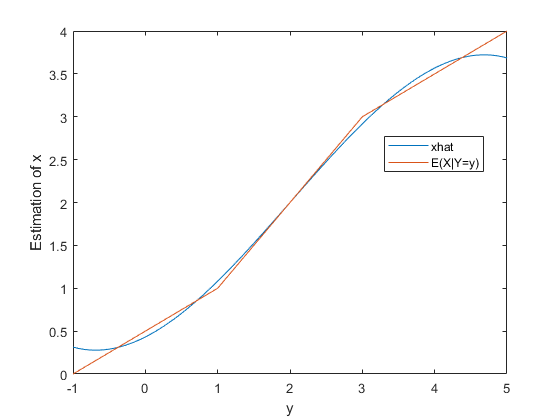

n = 100;
y = linspace(-1,5,n);

xhat = polyval(fliplr(M),y);
gx = (y+1)/2 .* (y>=-1 & y <=1) ...
    +y .* (y>1 & y <=3) ...
    +(y+3)/2 .* (y>3 & y<=5);

figure
plot(y,xhat)
hold on;
plot(y,gx)
legend('xhat','E(X|Y=y)','Location','best')
xlabel('y')
ylabel('Estimation of x')

## 1.2

clear
syms x y a
a = x*y;
fx = 1

fx = 1

fy = 1

fy = 1


g = [1;a;a^2;a^3];

Rxg = simplify(int(fy * int(fx*x*g', x, 0, 1), 0, 1))

$$Rxg = \left(\begin{array}{cccc} \frac{1}{4} & \frac{1}{14} & \frac{1}{30} & \frac{1}{52} \end{array}\right)$$

Rg = simplify(int(fy * int(fx*g*g', x, 0, 1), 0, 1))
Rx = simplify(int(fx*x*x',x,0,1))

M = Rxg*inv(Rg)
M = eval(M)
d2 = eval(Rx - M*Rxg')
sqrt(d2)

n = 1000;
a = linspace(0,1,n);

xhat = polyval(fliplr(M),a);
gx = (a-1)./log(a) .* (a>=0)

gx =          0    0.1446    0.1606    0.1717    0.1804    0.1878    0.1943    0.2002    0.2055    0.2104    0.2150    0.2193    0.2234    0.2273    0.2310    0.2346    0.2380    0.2413    0.2445    0.2476    0.2506    0.2535    0.2563    0.2591    0.2617    0.2644    0.2669    0.2695    0.2719    0.2743    0.2767    0.2790    0.2813    0.2835    0.2858    0.2879    0.2901    0.2922    0.2943    0.2963    0.2983    0.3003    0.3023    0.3042    0.3061    0.3080    0.3099    0.3118    0.3136    0.3154


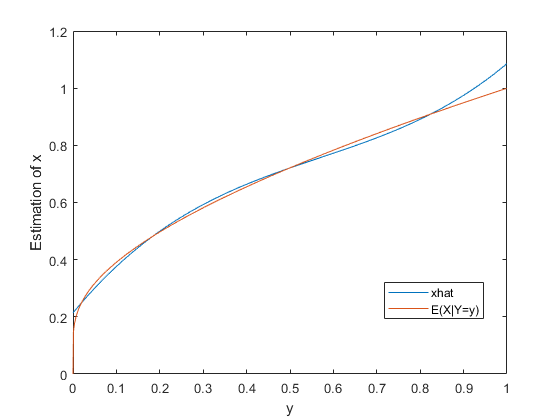

figure
plot(a,xhat)
hold on
plot(a,gx)
legend('xhat','E(X|Y=y)','Location','best')
xlabel('y')
ylabel('Estimation of x')